# Introduction to Curvilinear Regression Models

[⇦ Main Menu](matlab:open('../MainMenu.mlx'))

In this script, students explore the purpose of curvilinear regression and differentiate between model types. Curvilinear data, or data that does not follow a linear pattern, occurs in stress-strain curves, battery charging and discharging curves, pump and fan performance curves, dose-response curves, radioactive decay, diffusion processes, and more. 

[image: Illustration of a rechargable battery]

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternatively, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction in which you will explore the visualization of a concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is Curvilinear Regression?

In engineering, many variable relationships are inherently nonlinear. For example, the stress–strain curve of metals bends in the plastic region, robotic arm torque varies with joint angle due to gravity, diode current–voltage follows an exponential pattern, and cooling processes obey exponential decay.

 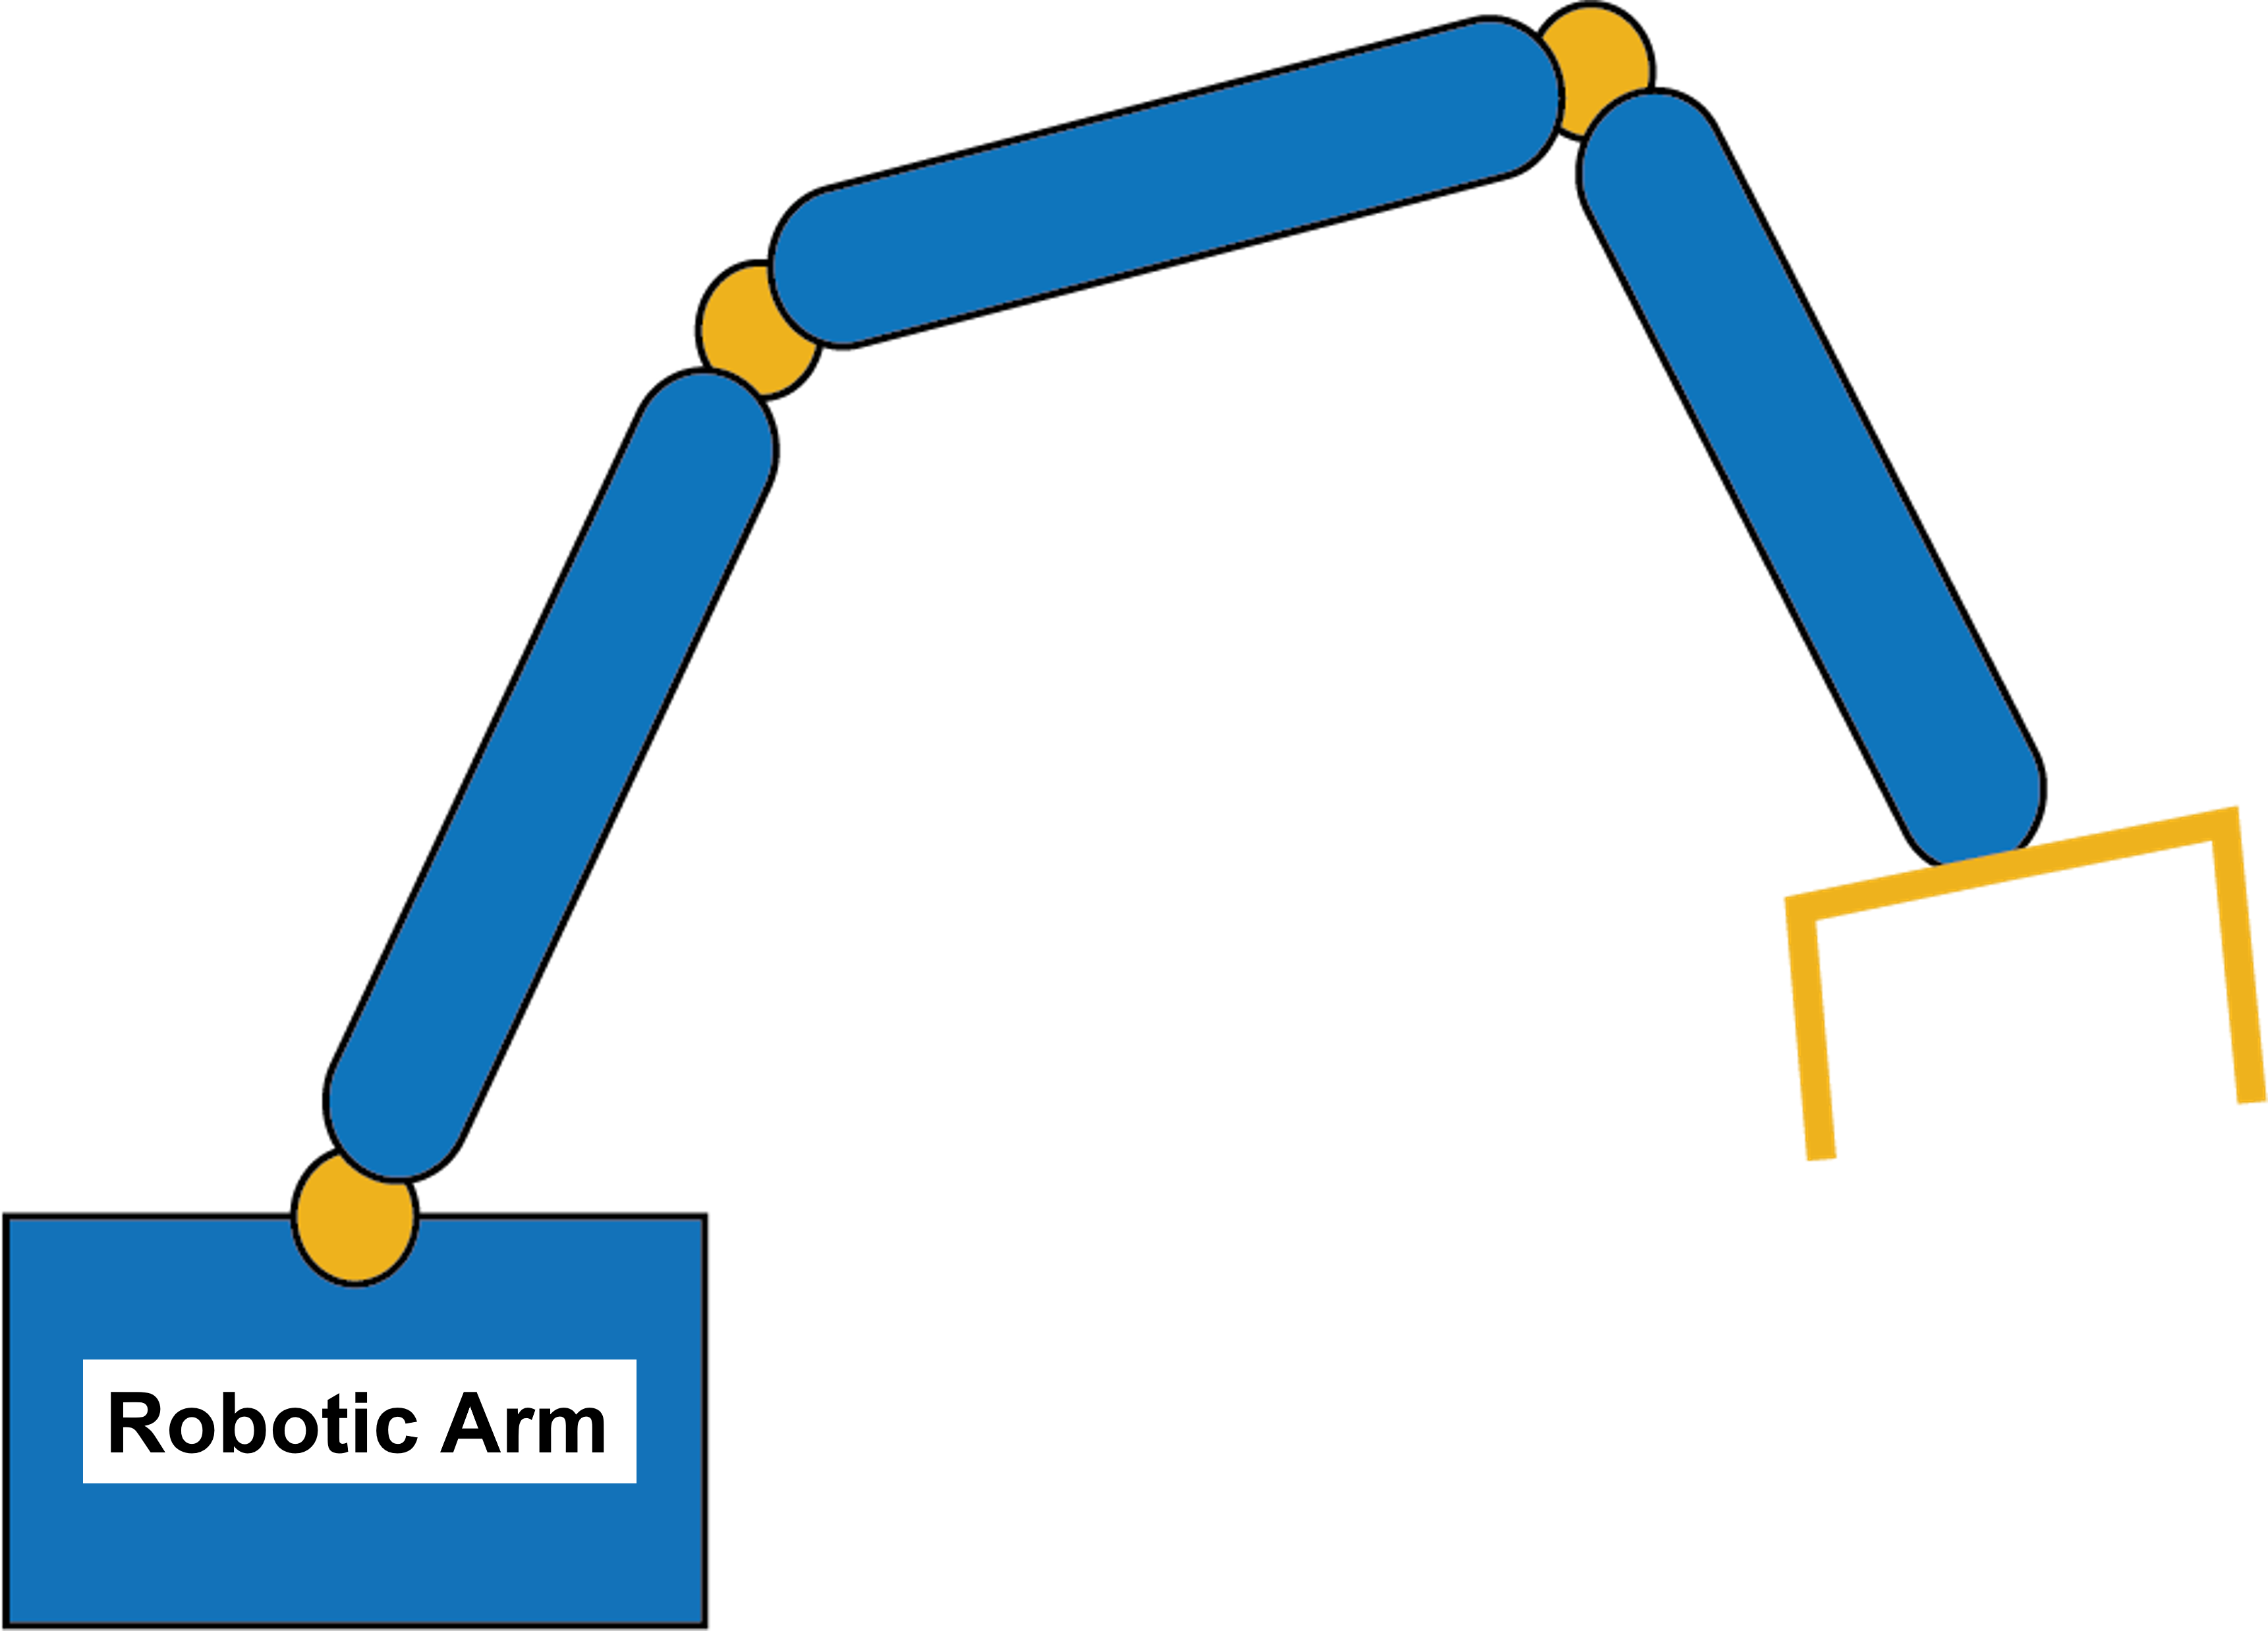

While linear models are simple and useful for approximations, they often fail when rates of change vary with input. To capture real system behavior, engineers use **curvilinear models **that better reflect underlying physics.

The two main types of **curvilinear regression** that we will explore are **polynomial regression** and **linearizable nonlinear regression**. 

- **Polynomial regression **is a type of regression analysis where a polynomial equation is fitted to the data, enabling the model to capture non-linear relationships by including higher-degree terms of the independent variable. 

- **Linearizable nonlinear regression **is a type of regression where the relationship between variables is inherently nonlinear (exponential growth, power laws, or saturation) but can be transformed into a linear form using mathematical techniques, allowing standard linear regression methods, discussed in [Linear Regression](matlab:open('./LinearRegression.mlx')), to be applied. 

## Polynomial Regression for Nonlinear Data

## 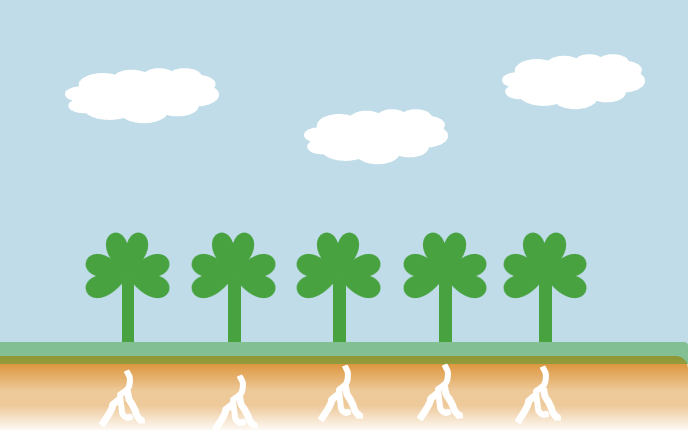

Farmers often struggle to predict how soil salinity affects crop yield (Thiam et al., 2025; Biology Insights, 2025). In an experiment, salinity near crop roots serves as the independent variable, and yield as the dependent variable. If the relationship appears linear, simple linear regression works; however, if it is curved, polynomial regression is better suited. **Polynomial regression** models nonlinear patterns by adding powers of the independent variable, such as squared, cubic, or higher-order terms, to capture complexity. 

Mathematically, a polynomial regression model can be written as:


$$y = a_0+a_1x+a_2x^2+a_3x^3 + \dots+a_px^p$$


where $a_0$ $a_1$, $\dots$, $a_p$ are the coefficients of the polynomial and $p$ is the degree of the polynomial chosen to fit the data best. Choosing a higher degree gives the model more flexibility and often lowers the sum of squared errors (**SSE**), a numerical measure of how closely the model follows the data. However, a smaller **SSE** does not necessarily mean the model best represents the underlying relationship. A model may closely trace individual data points while producing a curve that is unnecessarily complex or unrealistic for the system being studied.

In this activity, you will fit polynomial models of different degrees to the synthetic crop yield data, calculate their **SSE** values, and examine the resulting curves. Your goal is to minimize error while also identifying the model that most reasonably represents the relationship between soil salinity and crop yield.

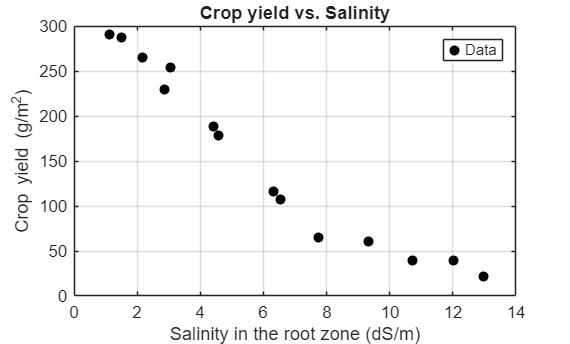

  **Try.  **Click the **button** below to load the data.

load NonlinearData.mat x y
disp("Data loaded.")
 

### Plot Data and Find Best-Fit

  **Try. **Find the best-fit for the crop yield data by selecting a fit from the **dropdown** menu below, and then clicking the **button** to plot the fit.

type = "Select";
 

[ft,plotTitle] = getFitTypeAndTitle(type);
if isempty(ft) && type == "Select"
    warning("Select a valid option.");
    return
end
[xData,yData] = prepareCurveData(x,y);

if isempty(ft)
    fitresult = [];
else
    [fitresult,gof] = fit(xData,yData,ft);
end

allTypes = ["Select","Linear","Polynomial of Order 2","Polynomial of Order 3","Polynomial of Order 4"]; % Include ALL options from your switch
ResultsTbl = compareAllFits(xData,yData,type,allTypes)
xlabel("{Salinity in the root zone (dS/m)}",Interpreter="latex")
ylabel("Crop Yield $\frac{g}{m^{2}}$",Interpreter="latex")

Salinity is reported in *deciSiemens per meter *$\left(\frac{dS}m\right)$ by measuring the electrical conductivity of the water or soil mixture.

 **Exercise 1. **For the dataset above, which type of fit seems best suited for this dataset? Use the dropdown menu to fit curves to the data and plot crop yield as a function of soil salinity in the root zone.

CheckAnswerNew("Exercise1","Select",[])% Options: "Select", "Linear", "Polynomial of Order 2","Polynomial of Order 3", and "Polynomial of Order 4"
 

### Find the Regression Line for Nonlinear Data

In the crop yield plot, there appears to be some curvature that you'd want to model. To do this, describe the relationship between a dependent and an independent variable with a polynomial, such that


$$y = a_0+a_1x^1+a_2x^2+a_3x^3 + \dots+a_px^p$$


where $a_0$ $a_1$, $\dots$, $a_p$ are the coefficients of the polynomial and $p$ is the degree of the polynomial chosen to best fit the data.

Polynomial regression models nonlinear relationships but remains linear in its parameters. The coefficients aren't combined or transformed nonlinearly, so the model can be estimated using standard linear regression techniques like least squares, making it a special case of linear regression. Therefore, we can still estimate the coefficients of the polynomial terms ($a_0$, $$a_1$$, $a_2$, $\dots$) using linear regression techniques.

  **Try. **Find the best fit for the crop yield data.

- Adjust the sliders to set the $a_0$, $a_1$, and $a_2$ coefficient values to find the best fit for the crop yield data.

- Press the 'Fit Data to a Polynomial of Degree 2' button to produce the plot. 

load NonlinearData.mat x y % Load the data
a0 = 425;
a1 =0  ;
a2 = 1;
 
PlotFit(x,y,[a2 a1 a0],0); % Call the helper function to plot the polynomial fit and the data

 **Reflect**. How easy or difficult was it to find the best coefficients? How did you determine that the line was a good fit?

 **Exercise 2. **Predict the crop yield for a `Salinity` of 6 dS/m. You can use a0, a1, a2, and `Salinity` as variables.

if ~isempty("fitresult")
    load NonlinearData.mat x y
    [xData, yData] = prepareCurveData(x,y);
    [fitresult,~] = fit(xData,yData,"poly2"); % Fit model to data.
end
a0 = fitresult.p1;
a1 = fitresult.p2;
a2 = fitresult.p3;
try
    Salinity ="0";
    CropYield = "a0+a1+Salinity+a2";
    [EqnFunc,TrueAns] = CheckEquation(CropYield);
catch
    warning("Enter MATLAB code.")
    return
end
 
if TrueAns == 1
    Salinity = str2double(Salinity);
    CropYield = round(EqnFunc(a0,a1,a2,Salinity));
    CheckAns(TrueAns,CropYield)
end

## Linearizable Nonlinear Regression

Linear and polynomial regression models work well for straight‑line and curved relationships, but many real‑world processes behave in ways that are more complex than these models allow. **Linearizable nonlinear regression** is used when the relationship between variables involves more complex dynamics, such as rapid growth, scaling behavior, or saturation effects. These models are not linear in their parameters and often require transformations or specialized fitting techniques. In this section, we will explore several common types of nonlinear regression models: exponential, power, saturation, and the S-curve. We introduce each model type with practical examples and visualizations to help you understand when and how to use them effectively.

### Exponential Fit

An **exponential fit** is appropriate when the dependent variable changes by a constant percentage for each unit increase in the independent variable. This type of relationship is modeled by the equation:


$$y=ae^{bx}$$
 

where $a$ and $b$ are constants. Exponential models commonly describe rapid growth or decay, such as the early spread of infections in epidemiology or the decline of pollutant concentrations in environmental systems.

An exponential model can be transformed into a linear form by taking the natural logarithm of the dependent variable $y$ and the associated constant term $a$, resulting in a linear equation:


$${\ln(y)}=bx+{\ln(a)}$$


A key indicator of an exponential relationship is that plotting $\text{ln}y$ versus $x$ produces a straight line, which allows the use of linear regression techniques on the transformed data. Equivalently, when the original $x$ and $y$ values are plotted on a **semilogy plot**, the data also appear linear. This makes exponential fits both powerful and accessible for analyzing dynamic systems in which the rate of change is proportional to the current value. Below, we show the exponential fit on a standard $x$-$y$ plot, the linearized exponential fit on a standard $x$–$y$ plot, and the original data displayed on a **semilogy plot**.

  **Try. **Click the **button** below to generate the exponential fit, the linearized exponential fit, and the exponential data on a semilogy plot.

 
% Demonstrates direct exponential fit and log-linearized approach.

% --- Exponential fit: y = a * exp(b*x) ---
rng shuffle
% --- Generate Paragraph Image   Exercise 2. Predict the crop yield for a salinity of 6 dS/m. You can use a0, a1, a2, CropYield as variables.

x = (0:0.2:5).';
yTrue = 2*exp(-0.2*x);

% Use multiplicative noise to preserve exponential structure
y = yTrue .* exp(0.05*randn(size(x)));

% --- Exponential fit: y = a * exp(b*x) ---
ft = "exp1";
opts = fitoptions(ft);
opts.StartPoint = [2 -0.2];
opts.Lower = [0 -Inf];
[fExp, gofExp] = fit(x,y,"exp1",opts);

% --- Prepare linearized data (filter y > 0) ---
mask = y > 0;
if ~all(mask)
    warning("Some y values ≤ 0 were removed for log-linearization.");
end
xLin = x(mask);
yLin = log(y(mask));

% --- Linear fit: ln(y) = p1*x + p2 ---
[fLin,~] = fit(xLin,yLin,"poly1");

% --- Visualization ---
figure
tiledlayout(1,3,Padding="compact",TileSpacing="compact")

% Left: Exponential Fit
nexttile
scatter(x,y,50,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3)
hold on
xDense = linspace(min(x),max(x),200).';
plot(xDense, fExp.a * exp(fExp.b * xDense),"-",LineWidth=2,SeriesIndex="none")
xlabel("$x$",Interpreter="latex")
ylabel("$y$",Interpreter="latex")
title("Exponential Fit: $y = a e^{b x}$",Interpreter="latex")
legend("Data","Nonlinear Fit",Location="best")
grid on
box on
hold off

% Middle: Linearized Fit
nexttile;
scatter(xLin,yLin,"filled",SeriesIndex=3)
hold on
plot(xLin,fLin.p1*xLin + fLin.p2,LineWidth=2,SeriesIndex="none")
xlabel("$x$",Interpreter="latex")
ylabel("$\ln(y)$",Interpreter="latex")
title("Linearized Exponential Fit",Interpreter="latex")
legend("Transformed Data","Linear Fit",Location="best")
grid on
box on
hold off

% Right: Linearized Fit
nexttile
semilogy(x,y,"o",MarkerFaceColor=[0.9290 0.6940 0.1250],SeriesIndex=3)
hold on
semilogy(xDense,fExp.a*exp(fExp.b*xDense),LineWidth=2,SeriesIndex="none")
xlabel("$x$",Interpreter="latex")
ylabel("$y$ (log scale)",Interpreter="latex")
title("Semilogy:"+newline+"Exponential Appears Linear",Interpreter="latex")
legend("Data","Fit",Location="best")
grid on
box on

%Make axes natural log
yl = ylim;
k = floor(log(yl(1))):ceil(log(yl(2)));
yticks(exp(k));
yticklabels(compose("e^{%d}",k));
hold off

sgtitle("Exponential Model and Linearization",FontWeight="bold")

### Power Fit

A **power fit** is used when the relationship between two variables follows a power‑law pattern, meaning the dependent variable scales with the independent variable raised to a constant exponent, typically written as

$y=ax^{b}$ .

Although a power‑law curve may resemble a polynomial over a limited range, it should not be modeled with one. Power‑law relationships are **multiplicative and scale‑invariant**, meaning proportional changes in the input lead to proportional changes in the output at all scales, whereas polynomial fits only approximate the curve’s shape and lack meaningful interpretation.

To make a power‑law relationship easier to analyze, both variables are transformed using logarithms, resulting in a linear equation. 

${\log{y}=b\log{x}+\log{a}$. 

This transformation allows the use of ordinary least squares regression while preserving the underlying scaling behavior. A key indicator that a power‑law model is appropriate is when the data form a straight line on a **log–log plot**. Below, we show the power‑law fit on a standard $x$ -$y$ plot, the linearized power fit using $\text{ln}x$ and $\text{ln}y$ on standard axes, and the original data displayed on log–log axes, where the power‑law relationship appears linear.

  **Try. **Click the **button** below to generate the power fit, the linearized power fit, and the exponential data on a log-log plot.

 
% Demonstrates direct power fit and log–log linearized approach

% --- Generate synthetic power-law data (multiplicative noise) ---
rng shuffle
x = (2:0.5:10).';
yTrue = 3*x.^2.5;

% Multiplicative noise preserves power-law structure
y = yTrue .* exp(0.08*randn(size(x)));

% --- Power fit: y = a*x^b ---
ft = "power1";
opts = fitoptions(ft);
opts.StartPoint = [3 2.5];
opts.Lower = [0 -Inf];

[fPower,gofPower] = fit(x,y,ft,opts);

% --- Prepare linearized data (filter positive values) ---
mask = (x > 0) & (y > 0);
if ~all(mask)
    warning("Nonpositive data removed for log-linearization.");
end

xLin = x(mask);
yLin = y(mask);

xLog = log10(xLin);
yLog = log10(yLin);

% --- Linear fit: log(y) = b log(x) + log(a) ---
[fLin,gofLin] = fit(xLog,yLog,"poly1");

% --- Visualization ---
figure
tiledlayout(1,3,Padding="compact",TileSpacing="compact")

% === 1) Nonlinear Power Fit (linear axes) ===
nexttile
scatter(x,y,50,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3)
hold on
xDense = linspace(min(x),max(x),300).';
plot(xDense,fPower.a*xDense.^fPower.b,"-",LineWidth=2,SeriesIndex="none")
xlabel("$x$",Interpreter="latex")
ylabel("$y$",Interpreter="latex")
title("Power Fit: $y = a x^{b}$",Interpreter="latex")
legend("Data","Nonlinear Fit",Location="northwest")
grid on
box on
hold off

% === 2) Linearized Fit (log-log transformed data, linear axes) ===
nexttile
scatter(xLog,yLog,"filled",SeriesIndex=3)
hold on
plot(xLog,fLin.p1*xLog + fLin.p2,LineWidth=2,SeriesIndex="none")
xlabel("$\log(x)$",Interpreter="latex")
ylabel("$\log(y)$",Interpreter="latex")
title("Linearized Power Fit",Interpreter="latex")
legend("Transformed Data","Linear Fit",Location="northwest")
grid on
box on
hold off

% === 3) Log–Log Axes (power appears linear) ===
nexttile
loglog(x,y,"o",MarkerFaceColor=[0.9290 0.6940 0.1250],SeriesIndex=3)
hold on
loglog(xDense,fPower.a*xDense.^fPower.b,LineWidth=2,SeriesIndex="none")
xlabel("$x$ (log scale)",Interpreter="latex")
ylabel("$y$ (log scale)",Interpreter="latex")
title("Log-Log:" + newline + "Power Law Appears Linear",Interpreter="latex")
legend("Data","Fit",Location="northwest")
grid on
box on
hold off

sgtitle("Power Law Model and Log–Log Linearization",Interpreter="tex",FontWeight="bold")

### Saturation Fit

A saturation fit is used when the relationship between two variables shows rapid initial growth that gradually slows and approaches a limiting value. Saturation relationships often follow the form:


$$y=\frac{x}{ax+b}$$


where $y$ is the dependent variable, $x$ is the independent variable, and $a$ and $b$ are constants that control the curve’s shape. This pattern is common in systems with diminishing returns or capacity limits, such as crop yields that plateau with increased fertilizer or drug responses that show diminishing benefits at higher doses.

To make this relationship easier to analyze using linear tools, the equation can be rearranged into a linear form:


$${\frac{1}y}=b\frac{1}x+{a}$$


This transformation allows you to apply ordinary least squares regression by plotting $\frac{1}{y$ against $\frac{1}{x}$. A key indicator that a saturation model is appropriate is when the original data shows a leveling-off trend that becomes linear after this transformation. 

  **Try. **Click the **button** below to generate the saturation fit and the linearized saturation fit.

 
figure
%% Saturation Model Fitting & Linearization

%--- Generate synthetic data ---
xSat = linspace(0.1,10,100).'; % column vector
a1True = 2;
a2True = 1;
ySat = xSat ./ (a1True * xSat + a2True) + 0.01 * randn(size(xSat));

%--- Prepare data for fitting ---
[xData, yData] = prepareCurveData(xSat,ySat);

%--- Define custom fit type ---
ft = fittype("x/(a1*x + a2)",independent="x",dependent="y");

%--- Define fit options ---
opts = fitoptions(ft);
opts.StartPoint = [1,1];% initial guess for [a1,a2]
opts.Lower = [0,0]; % enforce non‐negativity if appropriate

%--- Perform nonlinear fit ---
[fitresult,~] = fit(xData,yData,ft,opts);
%--- Plotting using tiledlayout ---
figure
tiledlayout(1,2,Padding="compact",TileSpacing="compact");

% Left tile: Data + nonlinear fit
nexttile
scatter(xSat,ySat,36,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3);
hold on
xDense = linspace(min(xSat),max(xSat),200).';
yPred = xDense ./ (fitresult.a1 * xDense + fitresult.a2);
plot(xDense,yPred,"-",LineWidth=2,SeriesIndex="none");
xlabel("$x$",Interpreter="latex");
ylabel("$y$",Interpreter="latex");
title("Saturation Fit: $y = \frac{x}{\,a_1 x + a_2\,}$",Interpreter="latex");
legend("Data","Nonlinear Fit",Location="best");
grid on
box on
hold off

% Right tile: Linearized version 1/y vs 1/x
nexttile
Ylin = 1 ./ ySat;
Xlin = 1 ./ xSat;
scatter(Xlin,Ylin,36,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3);
hold on
[xLinData,yLinData] = prepareCurveData(Xlin,Ylin);
linFit = fit(xLinData,yLinData,"poly1");
plot(Xlin,linFit.p1*Xlin+linFit.p2,"-",SeriesIndex="none",LineWidth=2);
xlabel("$1/x$",Interpreter="latex");
ylabel("1/y",Interpreter="latex");
title("Linearized Saturation Fit: $\frac{1}{y} = a_2 \left( \frac{1}{x} \right) + a_1$",Interpreter="latex")
legend("Transformed Data","Linear Fit",Location="southeast")
grid on
box on
hold off

sgtitle("Saturation Model and Linearization",FontWeight="bold");

### **Sigmoidal Curve (S-Curve) Fit**

**Sigmoidal Fit**

A **sigmoidal curve** is an S-shaped pattern often seen in systems with thresholds or saturation points. In this pattern, the dependent variable changes slowly at first, accelerates rapidly, and then levels off near a maximum. Such behavior appears in many real‑world systems, including biological population growth and enzyme–receptor binding, where responses accelerate under favorable conditions and eventually stabilize as limits are reached. Sigmoidal relationships are typically modeled using the form:


$$y=\frac{1}{1+e^{-bx$$


where $y$ is the dependent variable, $x$ is the independent variable. 

To make this relationship easier to analyze using linear tools, the equation can be rearranged into a linear form:

 
$$\ln\left(\frac{y}{1-y}\right) = bx$$


The linear transformation allows you to apply ordinary least squares regression by plotting $x$ against $\text{ln}\left({\frac{y}{1-y}}\right)$. A key indicator that a sigmoidal model is appropriate is when the original data shows an S-shaped pattern that becomes linear after this transformation.

  **Try. **Click the **button** below to generate the sigmoidal fit and the linearized sigmoidal fit.

 
%% Sigmoidal (Logistic) Fit & Linearization

%--- Generate synthetic sigmoidal data ---
xSigmoid = linspace(1,9,100).'; % column vector
kTrue = 1.0; % slope
x0True = 5.0; % midpoint
ySigmoid = 1 ./ (1 + exp(-kTrue*(xSigmoid - x0True))) + 0.02*randn(size(xSigmoid));

% Keep data in (0,1) for log-odds stability
ySigmoid = min(max(ySigmoid,1e-3),1-1e-3);

%--- Prepare data for fitting ---
[xData,yData] = prepareCurveData(xSigmoid,ySigmoid);

%--- Logistic fit (built-in model) ---
ft = fittype("logistic");
opts = fitoptions(ft); %#ok<NASGU>
opts = fitoptions(Method="NonlinearLeastSquares");
opts.Display = "Off";
opts.StartPoint = [1 0 1]; % [a,c,b] ~ amplitude,scale,center

[fitresult,gof] = fit(xData,yData,ft,opts);

%--- Plotting using tiledlayout ---
figure
tiledlayout(1,2,Padding="compact",TileSpacing="compact")

%% Left tile: Data + nonlinear logistic fit
nexttile
scatter(xSigmoid,ySigmoid,36,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3)
hold on

xDense = linspace(min(xSigmoid),max(xSigmoid),300).';
yPred = feval(fitresult,xDense);

plot(xDense,yPred,"-",LineWidth=2,SeriesIndex="none")

xlabel("$x$",Interpreter="latex")
ylabel("$y$",Interpreter="latex")
title("Sigmoidal Fit: $y = \frac{1}{1+e^{-bx}}$",Interpreter="latex")
legend("Data","Nonlinear Fit",Location="best")
grid on
box on
hold off

%% Right tile: Linearized form (log-odds)
nexttile
Ylin = log(ySigmoid ./ (1 - ySigmoid)); % Natural log to obtain the linearized form
Xlin = xSigmoid;

scatter(Xlin,Ylin,36,"filled",MarkerFaceAlpha=0.7,SeriesIndex=3)
hold on

[xLinData,yLinData] = prepareCurveData(Xlin,Ylin);
linFit = fit(xLinData,yLinData,"poly1");

plot(Xlin,linFit.p1*Xlin + linFit.p2,"-",LineWidth=2,SeriesIndex="none")

xlabel("$x$",Interpreter="latex")
ylabel("$\ln\!\left(\frac{y}{1-y}\right)$",Interpreter="latex")
title("Linearized S-Curve: $\ln\!\left(\frac{y}{1-y}\right)=bx$",Interpreter="latex")

legend("Transformed Data","Linear Fit",Location="best")
grid on
box on
hold off

sgtitle("Sigmoidal Model and Linearization",FontWeight="bold")

### Explore Synthetic Data

Having explored several types of curvilinear relationships, you will now analyze a randomly generated dataset and decide which model best describes it.

  **Try**. Generate a random synthetic data set by clicking the **button** below. 

% Generate data that loosely fits a quadratic regression model with increased noise
rng shuffle
xQuad = (0:0.1:10)'; % Define x values

% Define several candidate response generators and randomly pick one
rng shuffle
generators = {
    @() max(2.5 * exp(-0.3 * xQuad) + 0.5*randn(size(xQuad)),1e-6); % decaying exponential + noise (positive)
    @() 2.5 * xQuad - 1.0 + 2*randn(size(xQuad)); % linear with noise
    @() 3*xQuad.^2 - 2*xQuad + 1 + 2*randn(size(xQuad)) % quadratic with reduced noise
    };
genNames = {"Exponential";"Linear";"Polynomial"};
idx = randi(numel(generators));        % randomly select one generator
yQuad = generators{idx}();             % generate the response

% Display which generator was chosen
ChosenGeneratorName = genNames{idx};

% Plot the synthetic data
figure
scatter(xQuad,yQuad,"filled",DisplayName="Data",SeriesIndex=3)
title("Synthetic Data",Interpreter="latex")
xlabel("x",Interpreter="latex")
ylabel("y",Interpreter="latex")
grid on
box on
 

  **Try**. Select the best fit from the **dropdown menu** for the 'Synthetic Data' generated above.

% Fit a quadratic model to the data
FitChoice = "Select"; % Options: "Select", "Linear","Exponential", and "Polynomial"
if ~strcmp(FitChoice,"Select")
[ft,plotTitle] = getFitTypeAndTitle(FitChoice);
 

allTypes = ["Select","Exponential","Linear","Polynomial of Order 2"]; % Include ALL options from your switch
% Plot the fitted model and the data
figure
ResultsTbl = compareAllFits(xQuad,yQuad,FitChoice,allTypes);
disp(ResultsTbl)
else
    warning("Select a valid option.")
    return
end    

 **Exercise 3. **Select the best fit that best describes the 'Synthetic Data' above.

CheckAnswerNew("Exercise3","Select",ChosenGeneratorName);
 

## Try Curvilinear Regression on Your Own

- Learn to import datasets in MATLAB, build curvilinear regression models for battery lifetime, and for motor heat rise and thermal saturation, and use those models to predict future values in [Practice Curvilinear Regression: Polynomial Functions](matlab:open('.\TryCurvilinearPolynomial.mlx')).

[image: Illustration of a rechargable battery]

- Learn to import datasets and transform linearizable non-linear functions into linear regression models that will be used to predict future values in [Practice Curvilinear Regression: Linearizable Functions](matlab:open('./TryCurvilinear.mlx')).

## **Summary **

**Curvilinear regression** is used when the relationship between variables is not well captured by a straight line. We consider it when visual patterns in the data suggest curvature, when residuals from a linear model show systematic deviations, when domain knowledge implies nonlinearity, or when statistical metrics indicate improved model fit. Unlike linear regression, which assumes a constant rate of change, **curvilinear regression** allows us to model more nuanced relationships such as diminishing returns, tipping points, or saturation effects that are common in real-world scenarios. By fitting polynomial or nonlinear models, **curvilinear regression** provides a more accurate and meaningful representation of complex dynamics.

## Glossary

**Curvilinear regression: **A method for modeling curved relationships between variables, often using polynomial or nonlinear functions. (↑ Return to Text)

**Linearizable nonlinear regression**: A method for modeling relationships between variables using equations that are not linear in their parameters. (↑ Return to Text)

**Polynomial regression**: A type of regression that models data using a polynomial equation, useful for capturing curved trends. (↑ Return to Text)

## References

[Thiam, H. I., Owusu, V., Schuler, J., Lambarraa-Lehnhardt, F., & Hathie, I. (2025). *Impact of soil salinity adaptation on yields and food security in Fimela, Senegal*. Climatic Change.](https://link.springer.com/article/10.1007/s10584-025-03979-4)

[Biology Insights. (2025, April 29). *Soil Salinization: Impacts and Innovative Solutions*. https://biologyinsights.com/soil-salinization-impacts-and-innovative-solutions/](https://biologyinsights.com/soil-salinization-impacts-and-innovative-solutions)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternatively, select **Output inline **using the icon   at the top right of the Live Editor pane.

function yhat = PlotFit(x,y,A,ErrorFlag)

% Prepare data and compute the model predictions
powers = length(A)-1:-1:0;
X = x'.^powers;
yhat = A*X';

% Plot
figure
scatter(x,y,"o","filled",MarkerFaceAlpha=0.6,SeriesIndex=3);
DispLine = sprintf("y = " + join(A + ["x^{"+string(powers(1:end-1))+"}",""] ," + "),"Interpreter","tex");
xlim([min(x)-0.5,max(x)+0.5]);
ylim([min(y)-0.5,max(y)+0.5]);
hold on
fplot(@(x)A*(x'.^powers)',SeriesIndex="none",LineWidth=1.5);
legend("Data",DispLine,Location="eastoutside")
hold off
xlabel("$x$",Interpreter="latex")
ylabel("$y$",Interpreter="latex")
title("Linear model")
box on

if ErrorFlag
    hold on
    DispSSE = sprintf("\nErrors \nSSE = %12g",sum(yhat-y).^2);
    errorbar(x,y,min(yhat-y,0),max(yhat-y,0),".","vertical",DisplayName=DispSSE,SeriesIndex=3);
    hold off
end

end

function [ft,plotTitle] = getFitTypeAndTitle(type) % function to choose the fit plotted

switch type
    case "Select"
        ft = [];
        plotTitle = "";
        return
    case "Exponential"
        ft = fittype("exp1");
        plotTitle = "Exponential Fit";
    case "Linear"
        ft = fittype("poly1");
        plotTitle = "Linear Fit";
    case "Polynomial of Order 2"
        ft = fittype("poly2");
        plotTitle = "Polynomial Fit of Order 2";
    case "Polynomial of Order 3"
        ft = fittype("poly3");
        plotTitle = "Polynomial Fit of Order 3";
    case "Polynomial of Order 4"
        ft = fittype("poly4");
        plotTitle = "Polynomial Fit of Order 4";
      
    otherwise
        error("Unknown fit type: " + type);
end
end

function ResultsTbl = compareAllFits(x,y,type,allTypes)
% compareAllFits  Evaluate all fit options but only plot selected type

[xData,yData] = prepareCurveData(x,y);

n = numel(allTypes);

FitType   = strings(n,1);
PlotTitle = strings(n,1);
SSE       = NaN(n,1);

for k = 1:n

    currentType = allTypes(k);
    [ft,plotTitle] = getFitTypeAndTitle(currentType);

    FitType(k)   = currentType;
    PlotTitle(k) = plotTitle;

    if isempty(ft)
        Model{k} = [];
        continue
    end

    % Fit model
    [fitresult,gof] = fit(xData,yData,ft);

    SSE(k)   = gof.sse;
    Model{k} = fitresult;

    % Only plot the selected type and display its SSE
    if currentType == type
        plotRegressionGraph(xData,yData,plotTitle,fitresult,true)
        fprintf("The SSE for the %s Fit is %g\n", type, SSE(k));
    end
end

ResultsTbl = table(FitType,PlotTitle,SSE);
ResultsTbl = ResultsTbl(2:end,:);

end

function [EqnFunc,TrueAns] = CheckEquation(EquationStr) % Function to check exercise 2
arguments
    EquationStr (1,1) string % Must be a single string
end

% Initialize outputs
EqnFunc = [];
TrueAns = 0;

% Early exit if user has not entered code
if strcmpi(strtrim(EquationStr),"Enter MATLAB code.")
    warning("Enter MATLAB code.")
    return
end

varPattern = pattern("a0"|"a1"|"a2"|"Salinity");
variablesToCheck = ["a0","a1","a2","Salinity"];

% Build user function handle
EqnFunc = str2func("@(a0,a1,a2,Salinity)" + EquationStr);

% Extract variables from equation string
vars = extract(EquationStr,varPattern);

% Default answer
TrueAns = 1;

% Check presence of variables
for var = variablesToCheck
    Occurs = sum(strcmp(vars,var));
    if Occurs == 0
        warning("The variable '%s' is not present.",var);
        TrueAns = 0;
    elseif Occurs ==1 &&(var == "Salinity")
        warning("The variable '%s' is present only once.",var)
        TrueAns = 0;
    end
end
end

function [hScatter,hFit,hRes] = RegressFit(x,y) % Function to plot residuals for a given dataset
% Fit a linear model
p = polyfit(x,y,1);
yFit = polyval(p,x);

hScatter = scatter(x,y,"filled",SeriesIndex=6); % Create scatter plot
hold on
hFit = plot(x,yFit,"-",LineWidth=2,SeriesIndex=3); % Add regression line

% Plot residuals
hRes = gobjects(length(x),1); % Preallocate for graphics objects
for i = 1:length(x)
    hRes(i) = plot([x(i) x(i)],[yFit(i) y(i)],'--',SeriesIndex="none");
end
end

function CheckAnswerNew(exerciseID,option,ChosenGeneratorName)
%CHECKANSWERNEW  Check answers for exercises 1 and 3
%
%   Uses robust string comparisons and explicit logical conditions.

% Normalize everything to string scalars
exerciseID = string(exerciseID);
option     = strtrim(string(option));
ChosenGeneratorName = strtrim(string(ChosenGeneratorName));

switch exerciseID

    case "Exercise1"

        CorrectAnswer = "Polynomial of Order 2";
        hint = "Which fit has the lowest SSE value and fits the data without overfitting?";

        if option == CorrectAnswer
            disp("You are correct.")

        elseif option == "Select"
            warning("Select a valid option.")

        else
            warning(hint)
        end


    case "Exercise3"

        CorrectAnswer = ChosenGeneratorName;
        hint = "Which fit has the lowest SSE value and fits the data best?";

        % Explicit double condition as requested
        if option == ChosenGeneratorName
            disp("You are correct.")

        elseif option == "Select"
            warning("Select a valid option.")

        else
            warning(hint)
        end


    otherwise
        warning("Unknown exercise ID.")
end
end

function [yEquations,FitOptions] = SetEquations(x) % Function to set up equations
% Create a structure with all the fit data
yFit1 = 1./(1+(x./4.0).^1.9);
yFit2 = 1./(1+(x./4.5).^2.1);
yFit3 = 1./(1+(x./6.0).^1.5);
yFit4 = 1./(1+(x./5.3).^2.7);
yDefault = 0*x;

yEquations = {"Select","y = 1/(1+(x/4.0).^1.9)","y = 1/(1+(x/4.5)^2.1)","y = 1/(1+(x/6.0)^1.5)","y = 1/(1+(x/5.3)^2.7)"};
yTexEqns = {"Select","$y = \frac{1}{1 + \left(\frac{x}{4.0}\right)^{1.9}}$", "$y = \frac{1}{1 + \left(\frac{x}{4.5}\right)^{2.1}}$","$y = \frac{1}{1 + \left(\frac{x}{6.0}\right)^{1.5}}$","$y = \frac{1}{1 + \left(\frac{x}{5.3}\right)^{2.7}}$"};
FitOptions = struct("yFit",{yDefault,yFit1,yFit2,yFit3,yFit4},'FitEquation',yEquations,'LaTexEqns',yTexEqns,'FitLabel',{"Default","Fit 1","Fit 2","Fit 3","Fit4"});
end

function CheckAns(TrueAns,userResult) % Function to calculate value if all variables are present

if TrueAns == 1
    TrueVal = 12721;
end

if abs(userResult - TrueVal) < 1 % Compare to true value
    disp("You are correct.")
else
    disp("You are incorrect. Please check your calculations.")
    return
end

end

function plotRegressionGraph(xData,yData,plotTitle,fitresult,limitAxis)
% plotRegressionGraph  Plot data and display SSE with model type

if nargin < 6
    limitAxis = false;
end

figure
hold on

% Plot original data
scatter(xData,yData,"o","filled",SeriesIndex=3,MarkerFaceAlpha=0.6,DisplayName="Data")

% Define x-range
if limitAxis
    xEnd = 14;
else
    xEnd = max(xData)*1.1;
end

xFit = linspace(min(xData),xEnd,200);
yFit = feval(fitresult,xFit);

% Plot fit
plot(xFit,yFit,"-",LineWidth=2,DisplayName=plotTitle,SeriesIndex="none");

xlabel("$x$",Interpreter="latex");
ylabel("$y$",Interpreter="latex");
title(plotTitle)
legend(Location="bestoutside")
box on
grid on
axis padded
hold off

if limitAxis
    xlim([min(xData) 14]);
end

end

[](https://link.springer.com/article/10.1007/s10584-025-03979-4)